## Оценка параметров реального привода по данным из csv файла

### Читаем CSV файл

clear; clc;
% test_csv = readmatrix("motor_data/sin_4_8.csv")
test_csv = readmatrix("motor_data/sin_664.csv")

test_csv =          NaN         NaN         NaN         NaN         NaN
           0    12182959           0           0           0
           1    12191254           0           0           0
           2    12199253           0           0           0
           3    12207252           0           0           0
           4    12215251           0           0           0
           5    12223251           0           0           0
           6    12231250           0           0           0
           7    12239249           0           1           0
           8    12247258           0           1           0


% test_csv = readmatrix("motor_data/sin_664_acs712.csv")

% примерные параметры
% 1.9556
% 0.6153
% 1.9952
% 0.0087
% 0.0022

test_csv(2,2)

ans = 12182959

data_length = length(test_csv(:,2))-1

data_length = 704

time = test_csv(2:data_length+1, 2);    % мкс
ticks = test_csv(2:data_length+1, 3) / 15000 * 2 * pi;  % рад
input = test_csv(2:data_length+1, 4) / 100 * 12;    % В
current = test_csv(2:data_length+1, 5) / 1000;  % А
% current = test_csv(2:data_length+1, 5);  % А ACS712
current_orig = current;

t_start = time(1);
time = (time - t_start)/1000000;    % с

dticks = zeros(1, data_length);
dticks_orig = zeros(1, data_length);
dticks_smooth = zeros(1, data_length);

ddticks = zeros(1, data_length);
ddticks_orig = zeros(1, data_length);

dI = zeros(1, data_length);
dI_orig = zeros(1, data_length);

% no smooth works /7
% f_w = 1
% f_b = 0.1
% f_i = 1
% f_di = 0.05

% works for sin_664.csv
% f_w = 1
% f_b = 0.7
% f_i = 1
% f_di = 0.05

f_w = 1

f_w = 1

f_b = 0.7

f_b = 0.7000

f_i = 1

f_i = 1

f_di = 0.05

f_di = 0.0500


for n = 2:data_length
    dt = time(n)-time(n-1);

    dticks_orig(n) = ( ticks(n)-ticks(n-1) )/dt;
    ddticks_orig(n) = ( dticks_orig(n)-dticks_orig(n-1) )/dt;
    dI_orig(n) = ( current(n)-current(n-1) )/dt;

%     dticks(n) = ( ticks(n)-ticks(n-1) )/dt;
    dticks(n) = dticks(n-1)*(1-f_w) + f_w * ( ticks(n)-ticks(n-1) )/dt;

%     ddticks(n) = ( dticks(n)-dticks(n-1) )/dt;
%     ddticks(n) = ddticks(n-1)*(1-f_b) + f_b * ( dticks(n)-dticks(n-1) )/dt;
    ddticks(n) = ddticks(n-1)*(1-f_b) + f_b * ( dticks_orig(n)-dticks_orig(n-1) )/dt;
    
%     current(n) = current(n-1)*(1-f_i) + f_i * current(n);

%     dI(n) = ( current(n)-current(n-1) )/dt;
    dI(n) = dI(n-1)*(1-f_di) + f_di * ( current(n)-current(n-1) )/dt;
end

dticks = smooth(dticks, 3);

% works for sin_664.csv
current = smooth(current, 3);
ddticks = smooth(ddticks, 12);
dI = smooth(dI, 5);

% for ACS712
% current = smooth(current, 100);
% ddticks = smooth(ddticks, 12);
% dI = smooth(dI, 5);

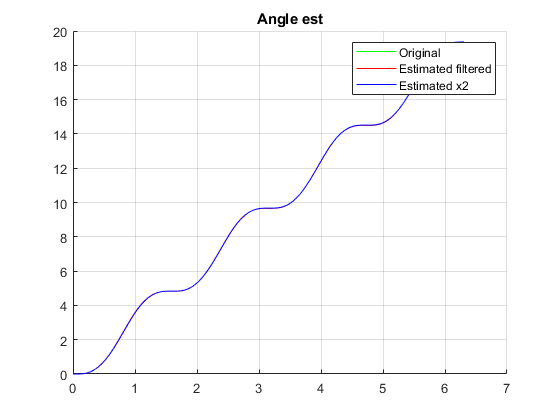

%check integration
q = zeros(1, data_length);
q1 = zeros(1, data_length);
w = zeros(1, data_length);
w1 = zeros(1, data_length);

for n = 2:data_length
    dt = time(n)-time(n-1);
    q(n) = q(n-1) + dticks(n) * dt;
    w(n) = w(n-1) + ddticks(n) * dt;
    w1(n) = w(n-1) + ddticks_orig(n) * dt;

    q1(n) = q1(n-1) + w(n) * dt;
end

figure;
hold on 
plot(time, ticks, "Color", "g")
plot(time, q, "Color", "r")
plot(time, q1, "Color", "b")
hold off
title("Angle est")
xlim("auto")
ylim("auto")
grid on
legend("Original", "Estimated filtered", "Estimated x2")

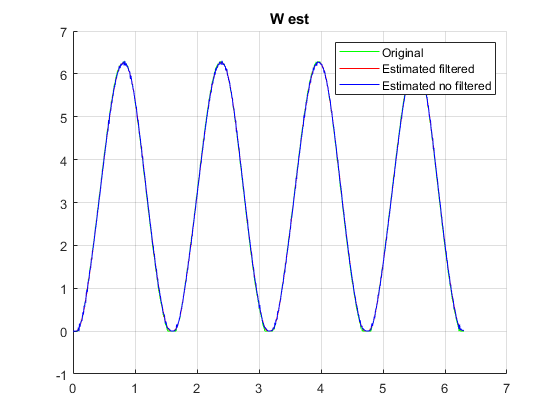


figure;
hold on
plot(time, dticks_orig, "Color", "g")
plot(time, w, "Color", "r")
plot(time, w1, "Color", "b")
hold off
title("W est")
xlim("auto")
ylim("auto")
grid on
legend("Original", "Estimated filtered", "Estimated no filtered")

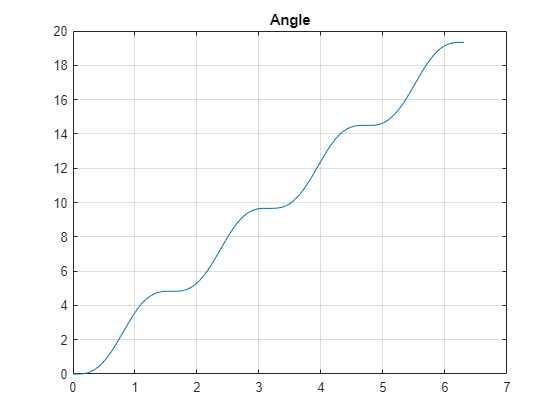

figure;
plot(time, ticks)
title("Angle")
xlim("auto")
ylim("auto")
grid on

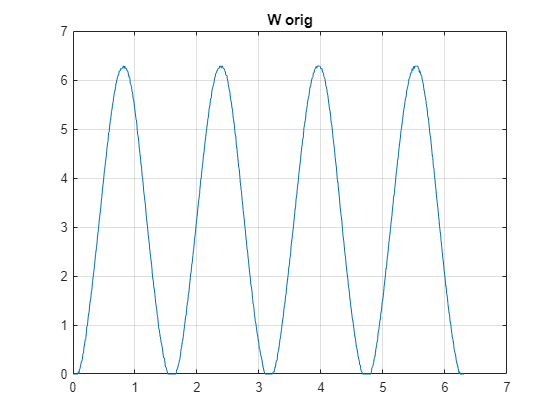


plot(time, dticks_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

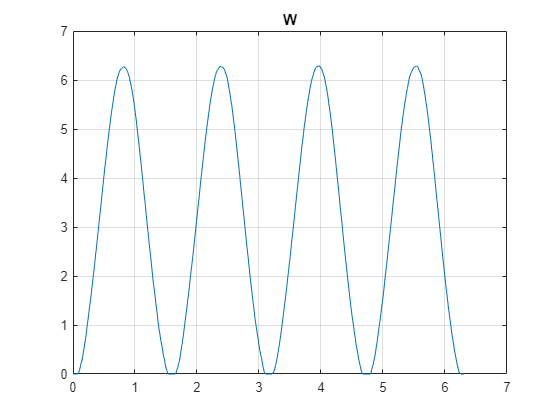


plot(time, dticks)
% hold
% plot(time, dticks_orig)
% hold 
title("W")
xlim("auto")
ylim("auto")
grid on

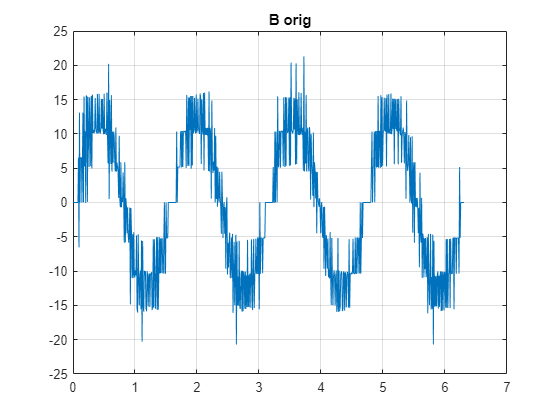


% plot(time_smooth, dticks_smooth)
% % plot(time, dticks_smooth)
% title("W smooth")
% xlim("auto")
% ylim("auto")
% grid on

plot(time, ddticks_orig)
title("B orig")
xlim("auto")
ylim("auto")
grid on

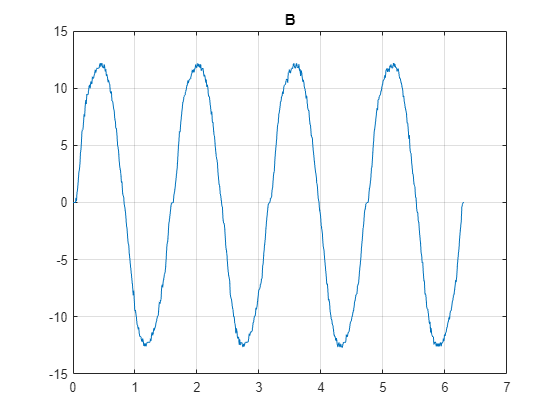


plot(time, ddticks)
title("B")
xlim("auto")
ylim("auto")
grid on

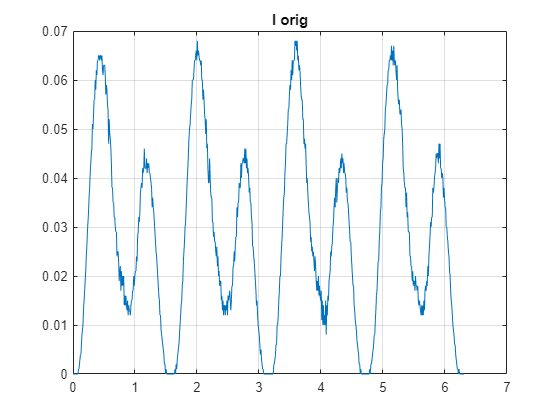


plot(time, current_orig)
title("I orig")
xlim("auto")
ylim("auto")
grid on

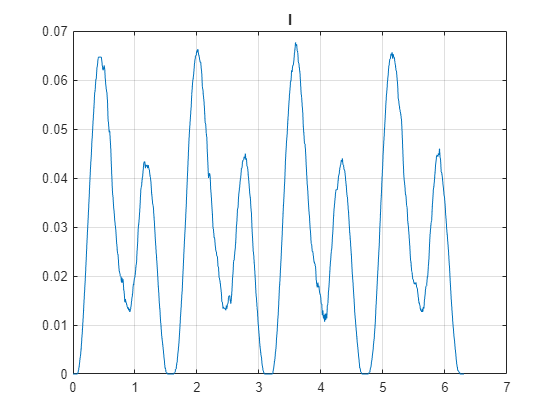


plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

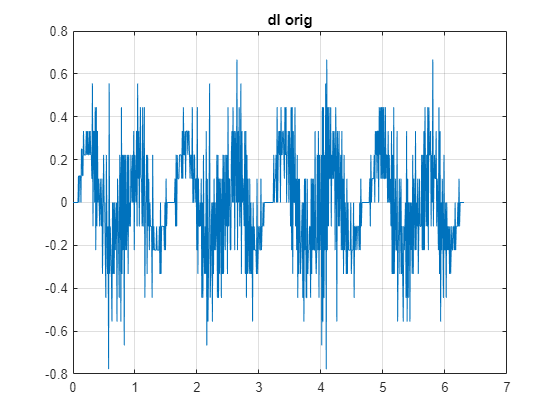


plot(time, dI_orig)
title("dI orig")
xlim("auto")
ylim("auto")
grid on

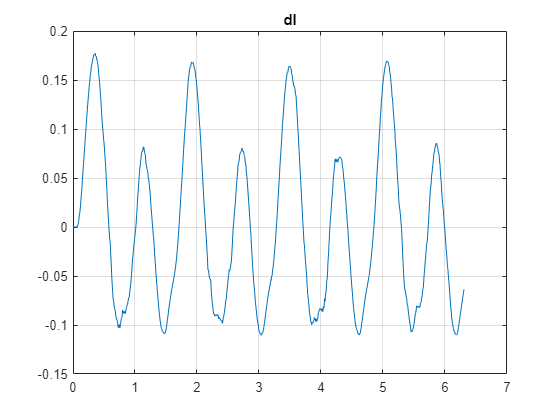


plot(time, dI)
title("dI")
xlim("auto")
ylim("auto")
grid on

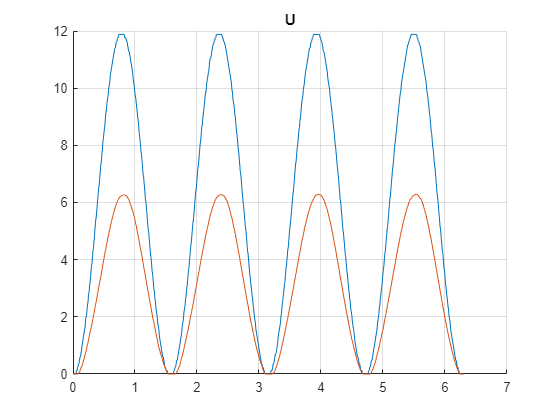


figure
title("U")
hold on
plot(time, input)
plot(time, dticks)
hold off
xlim("auto")
ylim("auto")
grid on

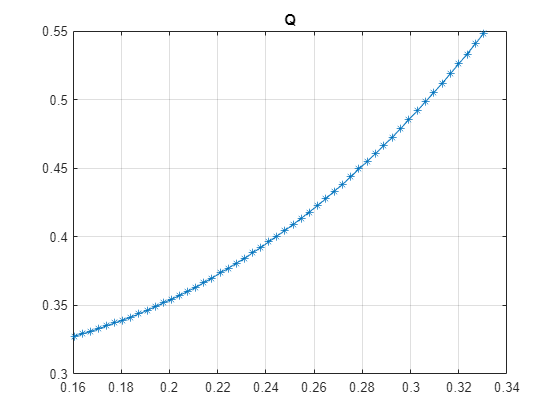

start = 50;
finish = 100;

figure;
plot(time(start:finish), ticks(start:finish), '*-')
title("Q")
xlim("auto")
ylim("auto")
grid on

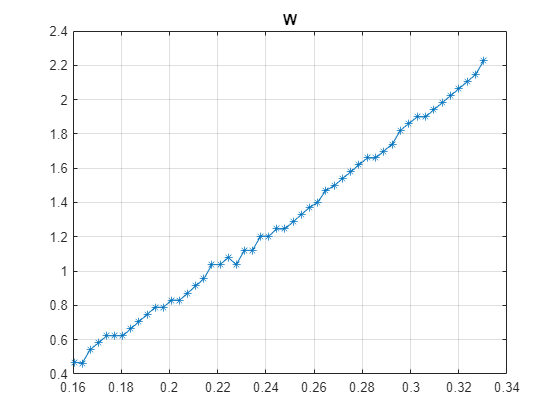


figure;
plot(time(start:finish), dticks(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

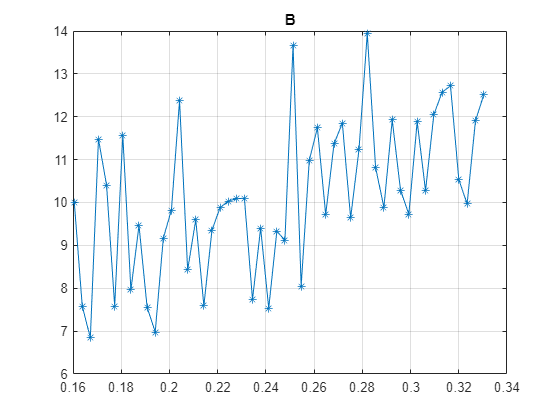


figure;
plot(time(start:finish), ddticks(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on

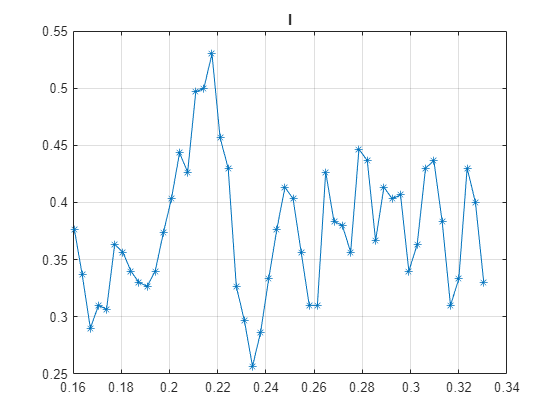


figure;
plot(time(start:finish), current(start:finish), '*-')
title("I")
xlim("auto")
ylim("auto")
grid on

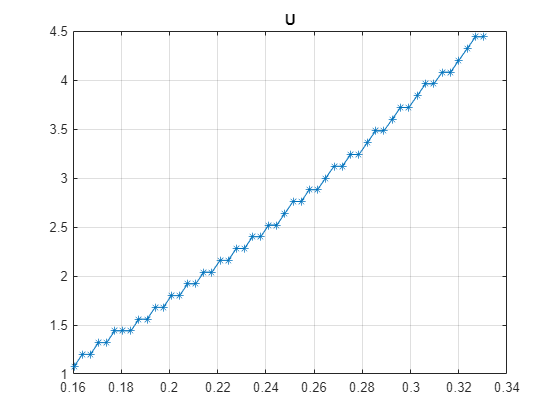


figure;
plot(time(start:finish), input(start:finish), '*-')
title("U")
xlim("auto")
ylim("auto")
grid on

### Определние параметров по данным с мотора

betta = 2 % коэффициент регуляризации

betta = 2

k0 = 100 % начальное значение матрицы коэффициентов

k0 = 100

I = eye(5) % диагональная единичная матрица

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


GAMMA_0 = k0.*I % матрица начальных значений коэффициентов

GAMMA_0 =    100     0     0     0     0
     0   100     0     0     0
     0     0   100     0     0
     0     0     0   100     0
     0     0     0     0   100



Th_hat = [0; 0; 0; 0; 0]

Th_hat =      0
     0
     0
     0
     0


dTh_hat = [0; 0; 0; 0; 0]

dTh_hat =      0
     0
     0
     0
     0



G_hat = GAMMA_0

G_hat =    100     0     0     0     0
     0   100     0     0     0
     0     0   100     0     0
     0     0     0   100     0
     0     0     0     0   100


dG_hat = zeros(5,5)

dG_hat =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

voz = zeros(2,2, data_length)

voz = voz(:,:,1) =

     0     0
     0     0


voz(:,:,2) =

     0     0
     0     0


voz(:,:,3) =

     0     0
     0     0


voz(:,:,4) =

     0     0
     0     0


voz(:,:,5) =

     0     0
     0     0


voz(:,:,6) =

     0     0
     0     0


voz(:,:,7) =

     0     0
     0     0


voz(:,:,8) =

     0     0
     0     0


voz(:,:,9) =

     0     0
     0     0


voz(:,:,10) =

     0     0
     0     0


voz(:,:,11) =

     0     0
     0     0


voz(:,:,12) =

     0     0
     0     0


voz(:,:,13) =

     0     0
     0     0


voz(:,:,14) =

     0     0
     0     0


voz(:,:,15) =

     0     0
     0     0


voz(:,:,16) =

     0     0
     0     0


voz(:,:,17) =

     0     0
     0     0


voz(:,:,18) =

     0     0
     0     0


voz(:,:,19) =

     0     0
     0     0


voz(:,:,20) =

     0     0
     0     0


voz(:,:,21) =

     0     0
     0     0


voz(:,:,22) =

     0     0
     0     0


voz(:,:,23) =

     0     0
     0     0


voz(:,:,24) =


cost = zeros(2, data_length);

h = 7

h = 7

% steps = 2:
% for n = 2:data_length/7
% for n = 2:h:data_length
for n = 2:90
    t = time(n);
    dt = time(n) - time(n-1);
    I_act = current(n);
    dI_act = dI(n);
    w_act = dticks(n);
    dw_act = ddticks(n);
    u_act = input(n);

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act];
    phi_T = phi';

%     voz(:, :, n) = voz(:, :, n-1) + phi_T*phi*(t - time(n-h)); % >= 0. больше единичной матрицы (поэлементно). если не такой - идентификация не работает

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; 0];

    A = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * A;
    
%     if isnan(dTh_hat(1))
%        dTh_hat = zeros(5,1);
%     end

    Th_hat = Th_hat + dTh_hat * dt;

    cost(:, n) = (U - phi_T*Th_hat);
end

Th_hat

Th_hat =     1.9556
    0.6153
    1.9952
    0.0087
    0.0022


eL = Th_hat(1)

eL = 1.9556

eR = Th_hat(2)

eR = 0.6153

eKw = Th_hat(3)

eKw = 1.9952

eKm = Th_hat(3)

eKm = 1.9952

eJ = Th_hat(4)

eJ = 0.0087

eLam = Th_hat(5)

eLam = 0.0022


% eL = abs(eL)
% eR = abs(eR)
% eKw = abs(eKw)
% eKm = abs(eKm)
% eJ = abs(eJ)
% eLam = abs(eLam)

Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL]

Ah =    -0.2507  229.8467
   -1.0203   -0.3146


Bh = [-1/eJ 0; 0 1/eL]

Bh =  -115.1971         0
         0    0.5114


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0



A = Ah

A =    -0.2507  229.8467
   -1.0203   -0.3146


B = Bh

B =  -115.1971         0
         0    0.5114


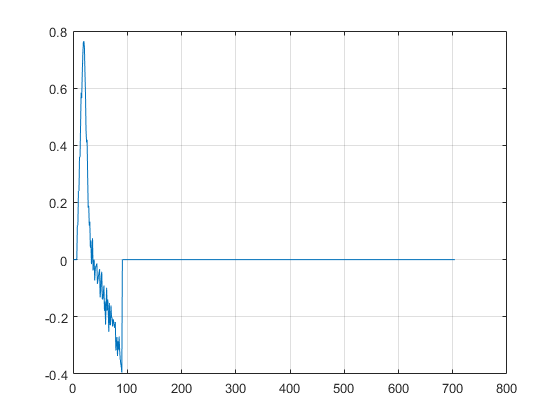


% -0.4 0.03
plot(cost(1,:));
grid on;

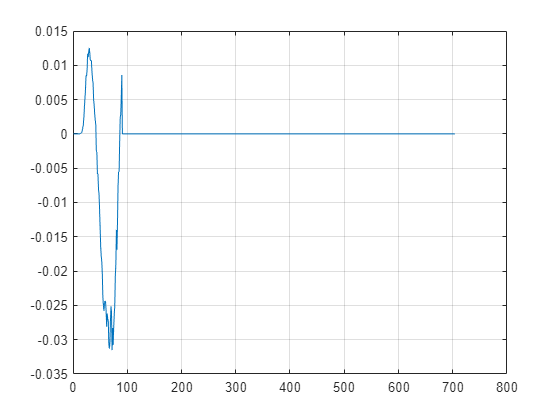

plot(cost(2,:));
grid on;

% plot(voz(1,1,:))

Amp = 6;
Bias = 6;
W = 4;
fi = 3.1415;

Const_input = [Amp Bias W fi];

t_f = time(data_length)

t_f = 6.3073

out1 = sim('model', t_f);

### Сравнение графиков мотора с оценочной моделью

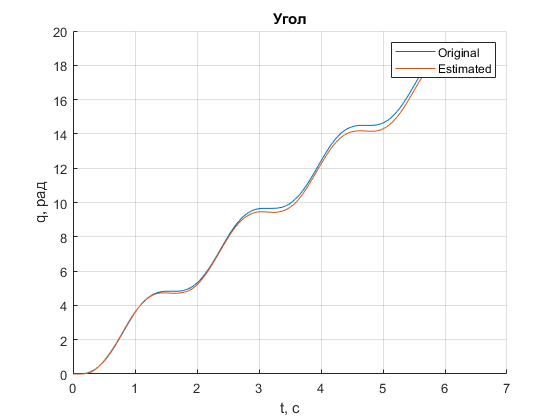

o = out1.simout;

xx = linspace(0, time(data_length), data_length);
q_m = spline(o.q.Time, o.q.Data, xx);
q_err = ticks - q_m';

figure
title("Угол")
grid on
hold on
plot(time, ticks)
plot(out1.simout.q.Time, out1.simout.q.Data)
hold off
xlabel("t, с")
ylabel("q, рад")
legend("Original", "Estimated")

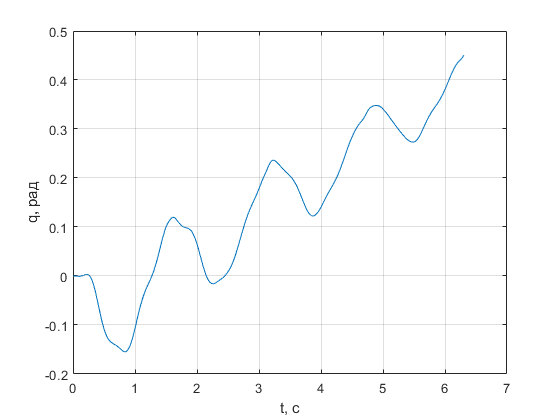

% xlim([0 0.1])

figure
title("Ошибка по углу")
plot(time, q_err)
xlabel("t, с")
ylabel("q, рад")

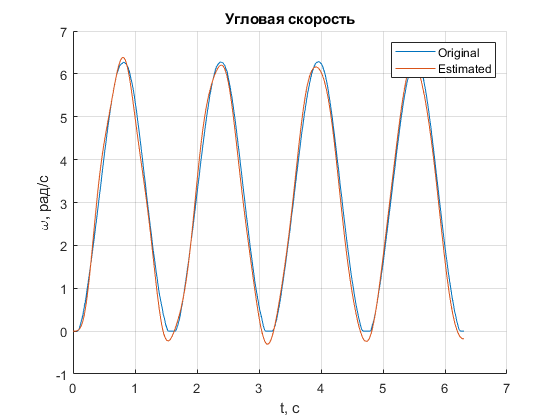


figure
title("Угловая скорость")
grid on
hold on
plot(time, dticks)
plot(out1.simout.q.Time, out1.simout.w.Data)
hold off
xlabel("t, с")
ylabel("\omega, рад/с")
legend("Original", "Estimated")

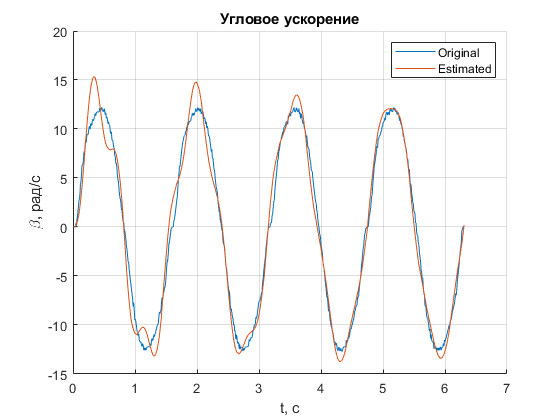


figure
title("Угловое ускорение")
grid on
hold on
plot(time, ddticks)
plot(out1.simout.q.Time, out1.simout.dw.Data)
hold off
xlabel("t, с")
ylabel("\beta, рад/с")
legend("Original", "Estimated")

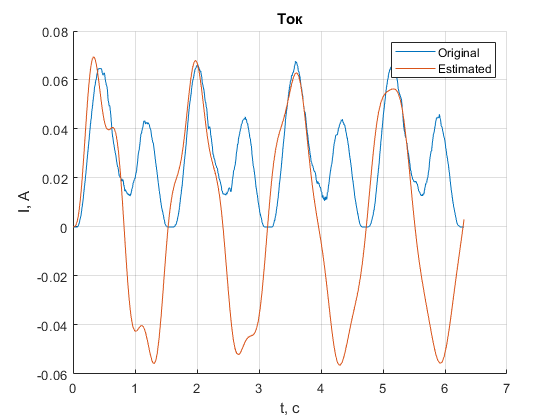


figure
title("Ток")
grid on
hold on
plot(time, current)
plot(out1.simout.q.Time, out1.simout.I.Data)
hold off
xlabel("t, с")
ylabel("I, А")
legend("Original", "Estimated")

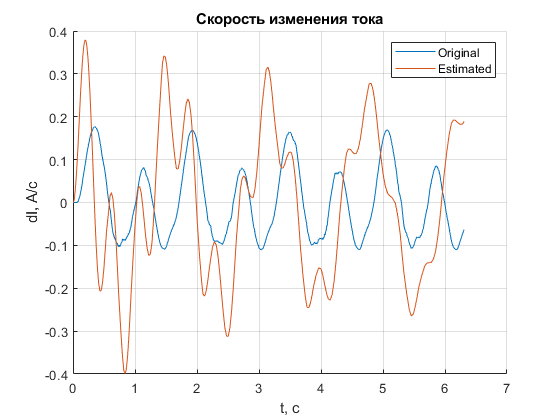


figure
title("Скорость изменения тока")
grid on
hold on
plot(time, dI)
plot(out1.simout.q.Time, out1.simout.dI.Data)
hold off
xlabel("t, с")
ylabel("dI, А/c")
legend("Original", "Estimated")

### Определние параметров по данным с мотора и данным тока из модели

xx = linspace(0, time(data_length), data_length);
I_m = spline(o.I.Time, o.I.Data, xx)

I_m =          0    0.0000    0.0000    0.0002    0.0004    0.0007    0.0012    0.0019    0.0028    0.0039    0.0053    0.0069    0.0087    0.0108    0.0132    0.0157    0.0185    0.0214    0.0245    0.0277    0.0310    0.0344    0.0378    0.0412    0.0445    0.0478    0.0509    0.0539    0.0567    0.0592    0.0615    0.0636    0.0653    0.0668    0.0680    0.0688    0.0693    0.0695    0.0694    0.0690    0.0684    0.0675    0.0663    0.0650    0.0635    0.0619    0.0601    0.0583    0.0564    0.0546


dI_m = spline(o.I.Time, o.dI.Data, xx)

dI_m =          0    0.0011    0.0062    0.0154    0.0285    0.0446    0.0634    0.0845    0.1070    0.1316    0.1579    0.1850    0.2123    0.2391    0.2646    0.2880    0.3105    0.3291    0.3462    0.3601    0.3699    0.3762    0.3791    0.3779    0.3728    0.3634    0.3506    0.3353    0.3151    0.2921    0.2683    0.2404    0.2089    0.1784    0.1488    0.1169    0.0820    0.0462    0.0117   -0.0212   -0.0526   -0.0822   -0.1092   -0.1335   -0.1546   -0.1724   -0.1867   -0.1974   -0.2044   -0.2078


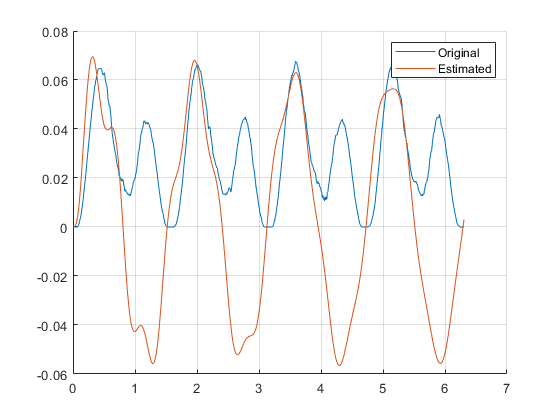


figure
hold on
plot(time, current)
plot(time, I_m)
hold off
legend("Original", "Estimated")

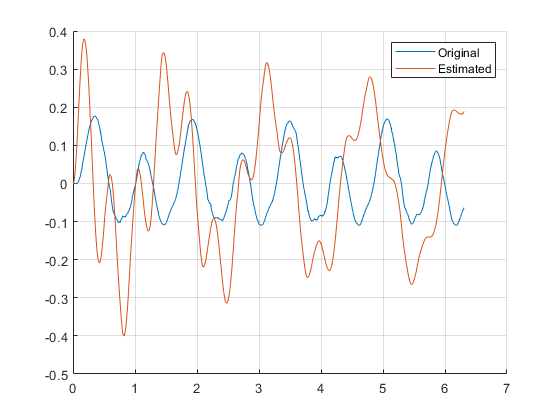



figure
hold on
plot(time, dI)
plot(time, dI_m)
hold off
legend("Original", "Estimated")

current = I_m;
dI = dI_m;

betta = 2; % коэффициент регуляризации

betta = 2

k0 = 100; % начальное значение матрицы коэффициентов

k0 = 100

I = eye(5); % диагональная единичная матрица

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


GAMMA_0 = k0.*I; % матрица начальных значений коэффициентов

GAMMA_0 =    100     0     0     0     0
     0   100     0     0     0
     0     0   100     0     0
     0     0     0   100     0
     0     0     0     0   100



Th_hat = [0; 0; 0; 0; 0];
dTh_hat = [0; 0; 0; 0; 0];

G_hat = GAMMA_0;
dG_hat = zeros(5,5);

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

voz = zeros(2,2, data_length);
cost = zeros(2, data_length);

for n = 2:data_length
    t = time(n);
    dt = time(n) - time(n-1);
    I_act = current(n);
    dI_act = dI(n);
    w_act = dticks(n);
    dw_act = ddticks(n);
    u_act = input(n);

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act];
    phi_T = phi';

%     voz(:, :, n) = voz(:, :, n-1) + phi_T*phi*(t - time(n-h)); % >= 0. больше единичной матрицы (поэлементно). если не такой - идентификация не работает

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; 0];

    A = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * A;
    
%     if isnan(dTh_hat(1))
%        dTh_hat = zeros(5,1);
%     end

    Th_hat = Th_hat + dTh_hat * dt;

    cost(:, n) = (U - phi_T*Th_hat);
end

Th_hat

Th_hat =     0.2921
    8.9101
    1.9135
    0.0081
    0.0003


eL = Th_hat(1)

eL = 0.2921

eR = Th_hat(2)

eR = 8.9101

eKw = Th_hat(3)

eKw = 1.9135

eKm = Th_hat(3)

eKm = 1.9135

eJ = Th_hat(4)

eJ = 0.0081

eLam = Th_hat(5)

eLam = 3.2711e-04


eL = abs(eL)

eL = 0.2921

eR = abs(eR)

eR = 8.9101

eKw = abs(eKw)

eKw = 1.9135

eKm = abs(eKm)

eKm = 1.9135

eJ = abs(eJ)

eJ = 0.0081

eLam = abs(eLam)

eLam = 3.2711e-04


Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL]

Ah =    -0.0406  237.2889
   -6.5507  -30.5035


Bh = [-1/eJ 0; 0 1/eL]

Bh =  -124.0099         0
         0    3.4235


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0



A = Ah

A =    -0.0406  237.2889
   -6.5507  -30.5035


B = Bh

B =  -124.0099         0
         0    3.4235



% -0.4 0.03
% plot(cost(1,:));
% plot(cost(2,:));
% plot(voz(1,1,:))

Amp = 6;
Bias = 6;
W = 4;
fi = 3.1415;

Const_input = [Amp Bias W fi];

t_f = time(data_length)

t_f = 6.3073

out2 = sim('model', t_f);

### Сравнение графиков мотора с оценочной моделью

o = out2.simout;

xx = linspace(0, time(data_length), data_length);
q_m = spline(o.q.Time, o.q.Data, xx);
q_err = ticks - q_m';

q_err =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0002
   -0.0004
   -0.0008
   -0.0013


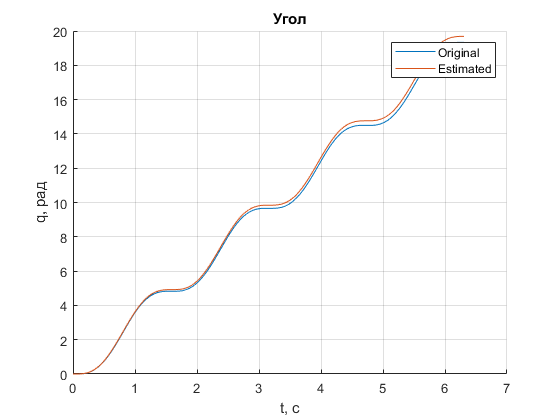


figure
title("Угол")
hold on
plot(time, ticks)
plot(o.q)
hold off
xlabel("t, с")
ylabel("q, рад")
legend("Original", "Estimated")

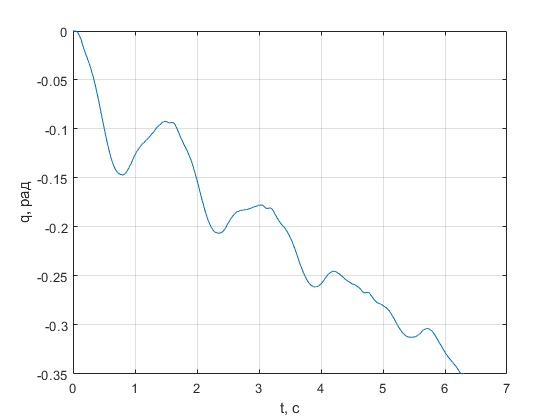


figure
title("Ошибка по углу")
plot(time, q_err)
xlabel("t, с")
ylabel("q, рад")

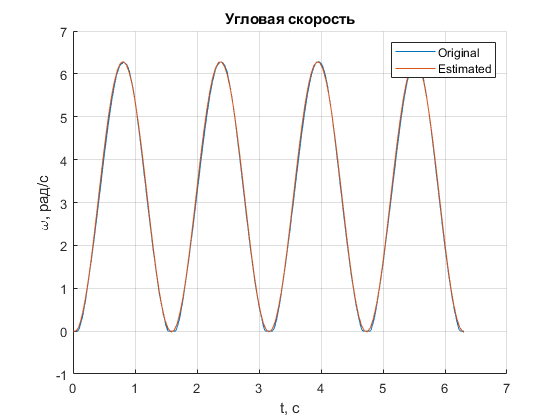


figure
title("Угловая скорость")
hold on
plot(time, dticks)
plot(o.w)
hold off
xlabel("t, с")
ylabel("\omega, рад/с")
legend("Original", "Estimated")

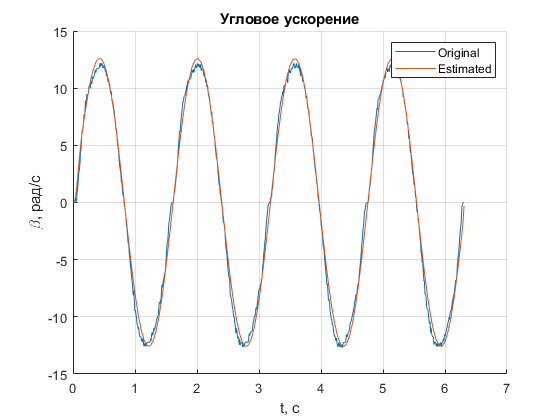


figure
title("Угловое ускорение")
hold on
plot(time, ddticks)
plot(o.dw)
hold off
xlabel("t, с")
ylabel("\beta, рад/с")
legend("Original", "Estimated")

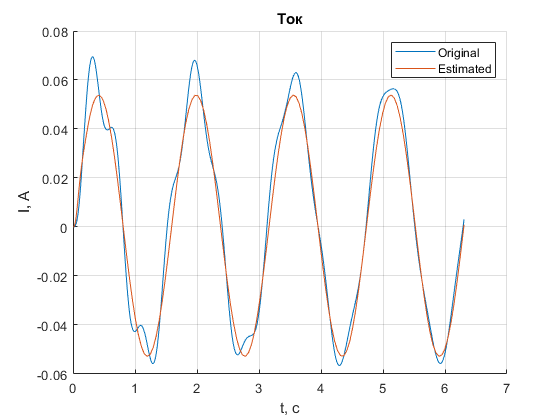


figure
title("Ток")
hold on
plot(time, current)
plot(o.I)
hold off
xlabel("t, с")
ylabel("I, А")
legend("Original", "Estimated")

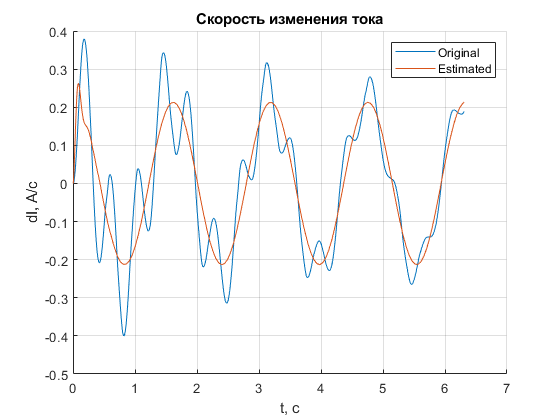


figure
title("Скорость изменения тока")
hold on
plot(time, dI)
plot(o.dI)
hold off
xlabel("t, с")
ylabel("dI, А/c")
legend("Original", "Estimated")